We are glad you are using our code. We will be happy to receive your feedback and help you if needed. If necessary, please contact us at szaksz@mm.bme.hu or at habib@mm.bme.hu. This code is provided freely for scientific purposes, and while not mandatory, we would greatly appreciate if users could acknowledge its use by citing our paper: Szaksz, B., Stepan, G., & Habib, G. (2024). Dynamical integrity estimation in time delayed systems: a rapid iterative algorithm. Journal of Sound and Vibration, 571, 118045.

This is an example code to show, how the algorithm can estimate the local integrity measure (LIM) of a 1DoF machining problem. A two dimensional parametric analysis is carried out, where the LIM is calculated varying the dimensionless chip width p and the spindle speed Omd.  The code runs parallel toolbox to speed up the computation.

For the currently set 50x50 grid, the computation time is ~15 minutes.

clear
close all
% clc
set(0,'defaulttextinterpreter','latex')
set(0, 'DefaultLegendInterpreter', 'latex')
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex')

Parameter values for the system and for the computation


% parameter values
zeta1 = 0.05;       % damping ratio
rho1 = 6109.6;      % experimental constant
rho2 = -54141.6;    % experimental constant
rho3 = 203769;      % experimental constant
h0 = .07;           % depth of cut 
eta2 = h0*(rho2+3*rho3*h0)/(rho1+2*rho2*h0+3*rho3*h0^2);    % second order nonlinearity
eta3 = h0^2*rho3/(rho1+2*rho2*h0+3*rho3*h0^2);    % third order nonlinearity

% for a 50x50 grid, the computation time is ~15 minutes
Omdvec = linspace(0.5,1.2,50);  % dimensionless spindle speed
pvec = linspace(0,0.8,50);      % chip width
tauvec = 2*pi./Omdvec;

% time discretization within the semi-discretization
r = 30;      % sampling delay number

% equilibrium point
xe=[0,0];

% variable of the phase space to be plot (unnecessary for this system,
% since it has only 1 DoF)
var1=1;
var2=2;

% number of step of the iteration
number_of_steps=50;

% maximal final time of each simulation
tfinal = 500;

% space boundary
spaceboundary=[-10,-10,10,10];   % space within the simulations are run i.e.: ([-q1,-dq1,q1,dq1])

% discretization of the phase space in each direction
discr=501;

% figure number
numfig = 103;


Linear stability analysis, to find the stability lobes. This provides the region within which the LIM should be investigated. 

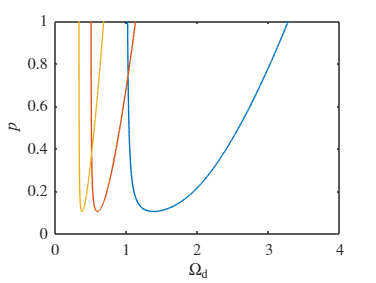

syms L om taus ps
assume(om,'real')
assume(ps,'real')
assume(taus,'real')
D1 = L^2+2*zeta1*L+1;

C1 = -real(subs(D1,L,1i*om));
C2 = -imag(subs(D1,L,1i*om));
omvec = [0:0.0003:3];
pcr = matlabFunction((C1^2+C2^2)/2/C1,'Vars',om);
pcrvec = pcr(omvec);
C1perC2 = matlabFunction(C1/C2,'Vars',om);
Omdcrvec = [];
for ipi=1:3
    Omdcrvec(:,ipi) = omvec*pi./((ipi)*pi+atan(C1perC2(omvec)));
end
pcrvec(pcrvec<0)=nan;
figure
plot(Omdcrvec,pcrvec)
ylim([0,1])
xlabel('$\Omega_\mathrm{d}$')
ylabel('$p$')

Computation of the Local Integrity Measure (LIM) of the system 

% computation of the LIM
R_final = zeros(length(Omdvec),length(pvec));
for iOmd = 1 : length(Omdvec)
    disp([num2str(iOmd) '/' num2str(length(Omdvec))])
    tau = tauvec(iOmd);
    dt = tau/(r+1/2); % time step of the semi-discretization
    for ipi = 1 : size(Omdcrvec,2)
        pcri(ipi) = interp1(Omdcrvec(:,ipi),pcrvec,Omdvec(iOmd));
    end
    parfor ip = 1 : length(pvec)
        p = pvec(ip);
        if p > min(pcri)
            R_final(iOmd,ip)=nan;
        else
            % in this case the parameter structure should be given within
            % the parfor loop
            par = struct('r',r,'dt',dt,'tau',tau); 
            par.zeta1 = zeta1;
            par.eta2 = eta2;
            par.eta3 = eta3;
            par.p = p;
            [par,weight,x1_q,x2_q] = dyn_machining1DoF(par);  % the dynamics of the system
        
            % computation of the LIM. Initial conditions selected as free vibration (init_type=3)
            [R_final(iOmd,ip),OutL,OutH]=compute_LIM_D_FP_HIC(xe,par,'weight',weight,'tfinal',tfinal, ...
                'var1',1,'var2',2,'plot_results',0,'plot_results_final',0,'automatic',1,'number_of_steps',number_of_steps,...
                'spaceboundary',spaceboundary,'discr',discr,'rep_fix_point',100,'rep_periodic',50,'num_of_cell_around_equilibrium',3,...
                'ind_check_conv',[1,2,3,4,5,6,7,8,9],'ind_check',[1,2,3,4,5,6,7,8,9],'num_fig',numfig,'init_type',3);
        end
    end
end

1/50
2/50
3/50
4/50
5/50
6/50
7/50
8/50
9/50
10/50
11/50
12/50
13/50
14/50
15/50
16/50
17/50
18/50
19/50
20/50
21/50
22/50
23/50
24/50
25/50
26/50
27/50
28/50
29/50
30/50
31/50
32/50
33/50
34/50
35/50
36/50
37/50
38/50
39/50
40/50
41/50
42/50
43/50
44/50
45/50
46/50
47/50
48/50
49/50
50/50


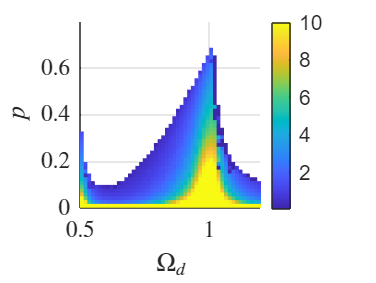


[pmatr,Omdmatr] = meshgrid(pvec,Omdvec);

figure;
surf(Omdmatr,pmatr,R_final,'EdgeColor','none')
colorbar
%caxis([0 9])
ylabel('$p$')
xlabel('$\Omega_d$')
set(gca,'FontSize',14)
xlim([0.5,1.2])
view(2)